**Defining System Matrices**

M=1000;
m1=100;
m2=100;
l1=20;
l2=10;
g=9.81;

A=[0 1 0 0 0 0; 
    0 0 -(m1*g)/M 0 -(m2*g)/M 0;
    0 0 0 1 0 0;
    0 0 -((M+m1)*g)/(M*l1) 0 -(m2*g)/(M*l1) 0;
    0 0 0 0 0 1;
    0 0 -(m1*g)/(M*l2) 0 -(g*(M+m2))/(M*l2) 0];

B=[0; 1/M; 0; 1/(M*l1); 0; 1/(M*l2)];

Q=[10 0 0 0 0 0;
0 0.00001 0 0 0 0;
0 0 1000 0 0 0;
0 0 0 0 0 0;
0 0 0 0 1000 0;
0 0 0 0 0 0];

R=0.0001;


C1=[1 0 0 0 0 0 ;];

C2=[
    0 0 1 0 0 0 ;
    0 0 0 0 1 0 ];

C3=[1 0 0 0 0 0 ;
    0 0 1 0 0 0 ;
    ];

C4=[1 0 0 0 0 0 ;
    0 0 1 0 0 0 ;
    0 0 0 0 1 0 ];

**Observability**

% A_sub=double(subs(A,[M m1 m2 l1 l2 g ],[1000,100,100,20,10,-9.81]));
% B_sub=double(subs(B,[M m1 m2 l1 l2 g ],[1000,100,100,20,10,-9.81]));A

obv_1=obsv(A,C1);
ob1=rank(obv_1);

obv_2=obsv(A,C2);
ob2=rank(obv_2);

obv_3=obsv(A,C3);
ob3=rank(obv_3);

obv_4=obsv(A,C4);
ob4=rank(obv_4);

disp("The observability of C1 is" +" "+ob1)

The observability of C1 is 6



disp("The observability of C2 is" +" "+ob2)

The observability of C2 is 4



disp("The observability of C3 is" +" "+ob3)

The observability of C3 is 6



disp("The observability of C4 is" +" "+ob4)

The observability of C4 is 6


**Luenberger Observer **

[K,P,Poles]=lqr(A,B,Q,R);
poles=[-10,-20,-30,-40,-50,-60];

LO1=place(A',C1',poles)'

LO1 = 1.0e+09 *

    0.0000
    0.0000
   -0.3658
   -1.4798
    0.3651
    1.4632


LO3=place(A',C3',poles)'

LO3 = 1.0e+05 *

    0.0013    0.0002
    0.0549    0.0147
    0.0000    0.0008
    0.0028    0.0160
   -0.9181   -0.3547
   -4.7392   -2.1866


LO4=place(A',C4',poles)'

LO4 = 1.0e+03 *

    0.0875   -0.0093    0.0000
    1.8320   -0.4167   -0.0010
   -0.0100    0.0925   -0.0000
   -0.4532    2.0673   -0.0001
    0.0000   -0.0000    0.0300
    0.0000   -0.0001    0.1989



AL1=[(A-(B*K)) B*K;
    zeros(size(A)) A-LO1*C1];
BL1 = [B ; zeros(size(B))];

CL1=[C1 zeros(size(C1))];

DL1=0;



AL3=[A-(B*K) B*K;
    zeros(size(A))  A-(LO3*C3)];

BL3=[B;zeros(size(B))];

CL3=[C3 zeros(size(C3))];

DL3=0;


AL4=[A-(B*K) B*K;
   zeros(size(A))  A-(LO4*C4)];

BL4=[B;zeros(size(B))];

CL4=[C4 zeros(size(C4))];

DL4=0;

SS1= ss(AL1,BL1,CL1,DL1);
SS3= ss(AL1,BL3,CL3,DL3);
SS4= ss(AL1,BL4,CL4,DL4);

**Plotting Response of System to Step and Initial Conditions **

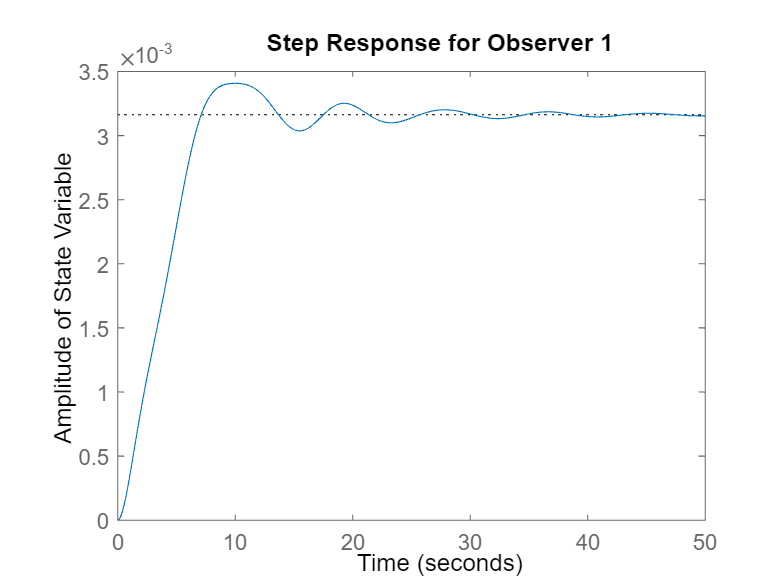

figure
step(SS1)
title('Step Response for Observer 1')
xlabel('Time')
ylabel('Amplitude of State Variable')

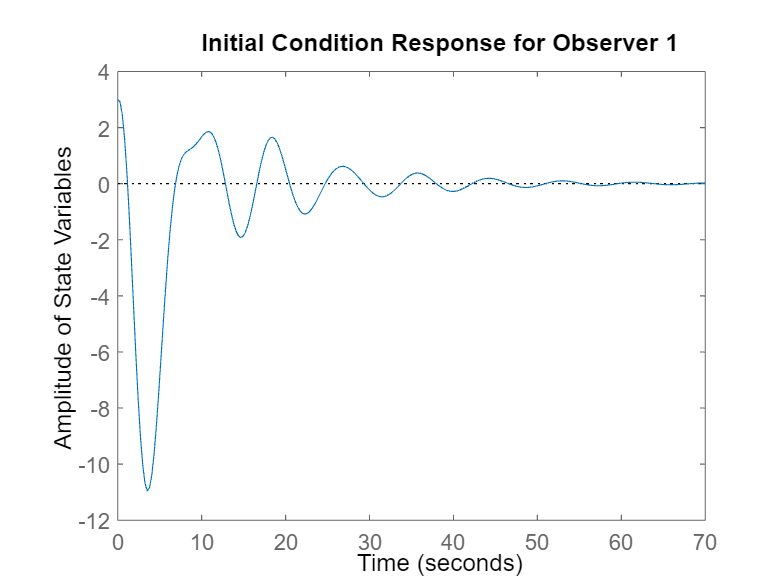

initial_state =  [3,0.3,deg2rad(20),1,deg2rad(-10),2,0,0,0,0,0,0];
figure 
initial(SS1,initial_state)
title('Initial Condition Response for Observer 1')
xlabel('Time')
ylabel('Amplitude of State Variables')

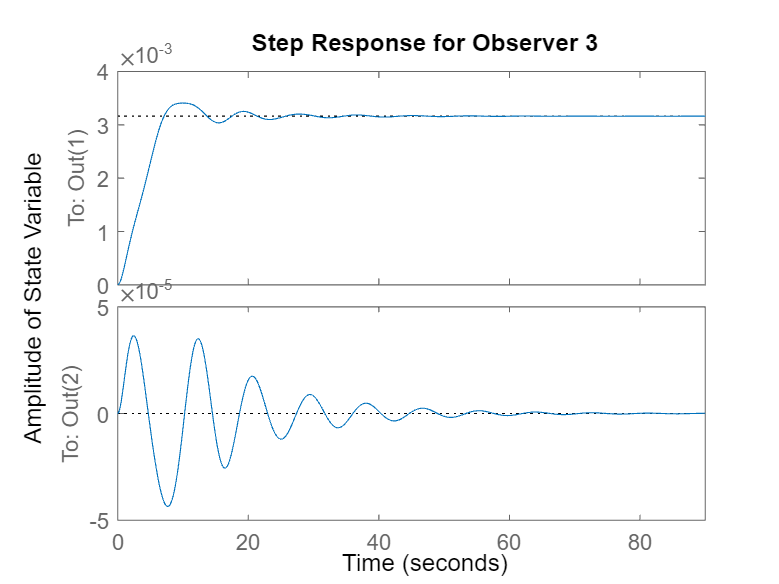

figure
step(SS3)
title('Step Response for Observer 3')
xlabel('Time')
ylabel('Amplitude of State Variable')

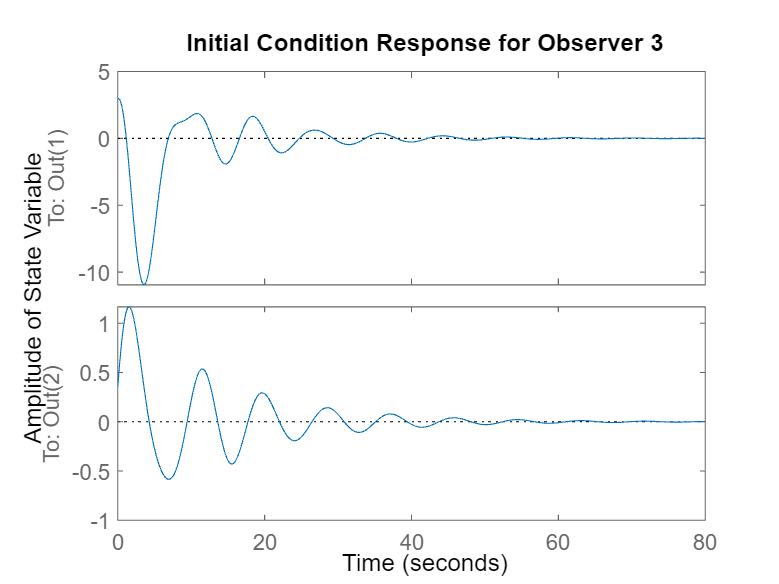

 
figure 
initial(SS3,initial_state)
title('Initial Condition Response for Observer 3')
xlabel('Time')
ylabel('Amplitude of State Variable')

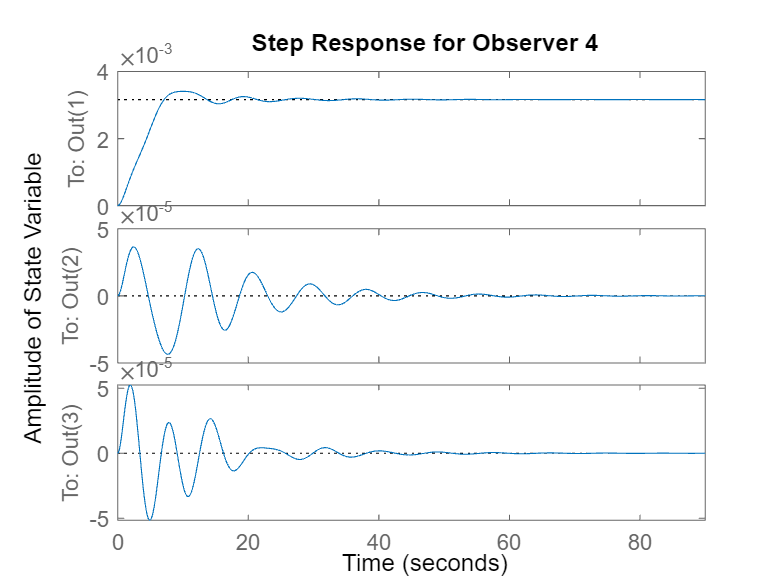

figure
step(SS4)
title('Step Response for Observer 4')
xlabel('Time')
ylabel('Amplitude of State Variable')

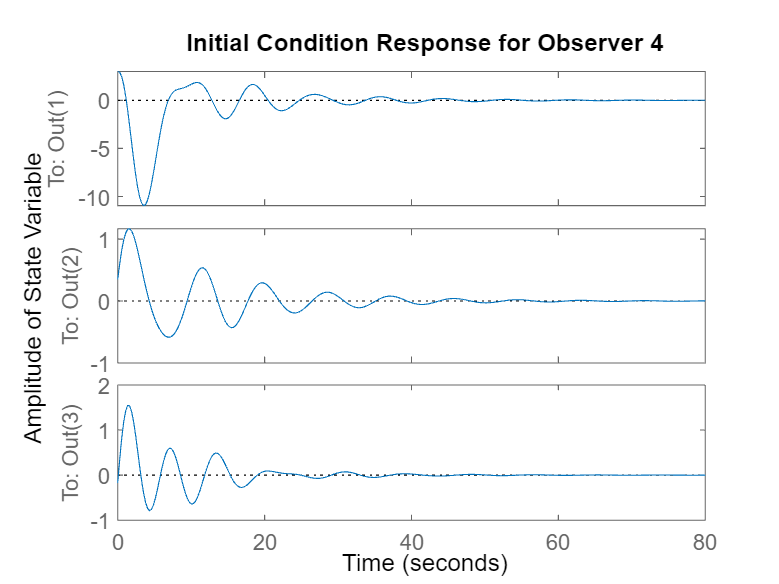

figure 
initial(SS4,initial_state)
title('Initial Condition Response for Observer 4')
xlabel('Time')
ylabel('Amplitude of State Variable')

**Plotting Response of Non Linear System **

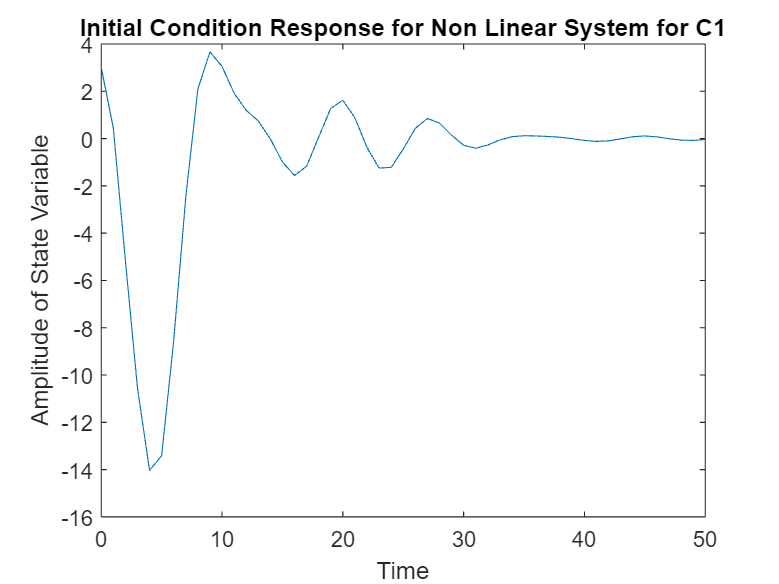

time_span = 0:1:50;
[time,out] = ode45(@(time,input)non_linear(time,input,C1),time_span,initial_state);
figure
plot(time,out(:,1))
title('Initial Condition Response for Non Linear System for C1')
xlabel('Time')
ylabel('Amplitude of State Variable')

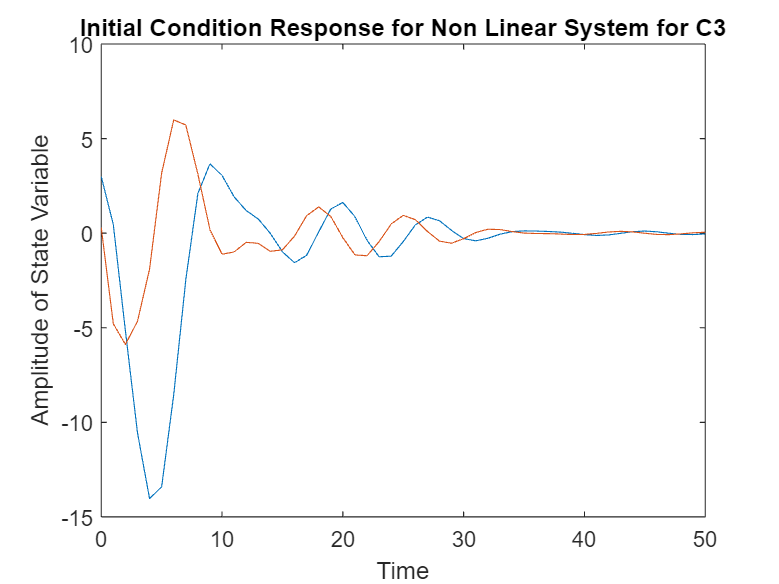


time_span = 0:1:50;
[time,out] = ode45(@(time,input)non_linear(time,input,C3),time_span,initial_state);
figure
plot(time,out(:,1:2))
title('Initial Condition Response for Non Linear System for C3')
xlabel('Time')
ylabel('Amplitude of State Variable')

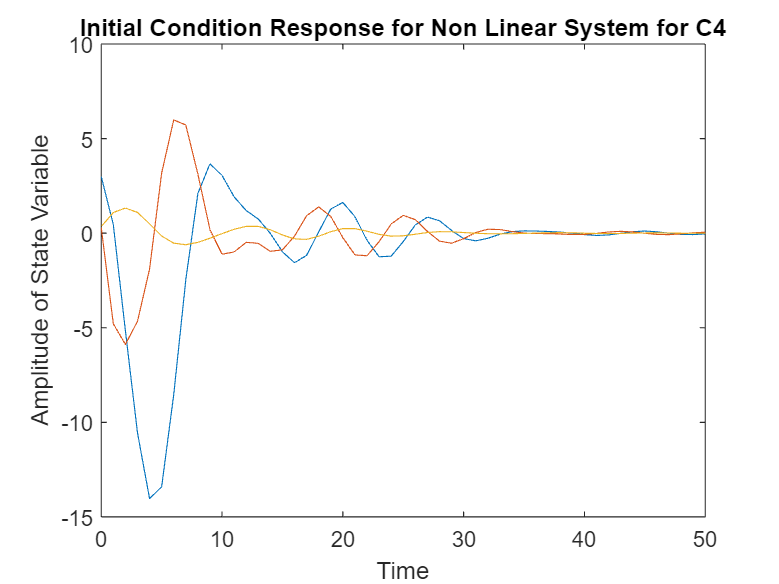

time_span = 0:1:50;
[time,out] = ode45(@(time,input)non_linear(time,input,C4),time_span,initial_state);
figure
plot(time,out(:,1:3))
title('Initial Condition Response for Non Linear System for C4')
xlabel('Time')
ylabel('Amplitude of State Variable')

function value = non_linear(time,input,C)
M=1000;
m1=100;
m2=100;
l1=20;
l2=10;
g=9.81;

A=[0 1 0 0 0 0; 
    0 0 -(m1*g)/M 0 -(m2*g)/M 0;
    0 0 0 1 0 0;
    0 0 -((M+m1)*g)/(M*l1) 0 -(m2*g)/(M*l1) 0;
    0 0 0 0 0 1;
    0 0 -(m1*g)/(M*l2) 0 -(g*(M+m2))/(M*l2) 0];

B=[0; 1/M; 0; 1/(M*l1); 0; 1/(M*l2)];


Q=[10 0 0 0 0 0;
0 0.00001 0 0 0 0;
0 0 1000 0 0 0;
0 0 0 0 0 0;
0 0 0 0 1000 0;
0 0 0 0 0 0];

R=0.0001;



th1 = input(3);
th2 = input(5);

th_dot1 = input(4);
th_dot2 = input(6);
K= lqr(A,B,Q,R);

F=-K*input(1:6);

x_ddot =((F-(m1*sin(th1))*g*cos(th1)+l1*(th_dot1.^2))-(m2*sin(th1)*(g*cos(th2)+l2*(th_dot2^2))))/((M+(m1*(sin(th1).^2)))+m2*(sin(th2).^2));
th_ddot1 = (x_ddot*cos(th1)-g*sin(th1))/l1;
th_ddot2 = (x_ddot*cos(th2)-g*sin(th2))/l2;

desired_poles = [-10;-20;-30;-40;-50;-60];
L = place(A',C',desired_poles)';

estimator = (A-L*C)*input(7:12);

value = zeros(12,1);
value(1) = input(2); 
value(2) = x_ddot;
value(3) = input(4);
value(4) = th_ddot1;
value(5) = input(6);
value(6) = th_ddot2;
value(7) = estimator(1);
value(8) = estimator(2);
value(9) = estimator(3);
value(10) = estimator(4);
value(11) = estimator(5);
value(12) = estimator(6);
end